% Create an audio recorder object
fs = 44100; % Sampling frequency (44.1 kHz)
bits = 16;  % Bit depth
channels = 1; % Mono recording
duration = 1; % Duration in seconds

recObj = audiorecorder(fs, bits, channels);

% Start recording
disp('Start speaking...');

Start speaking...


recordblocking(recObj, duration);
disp('Recording stopped.');

Recording stopped.


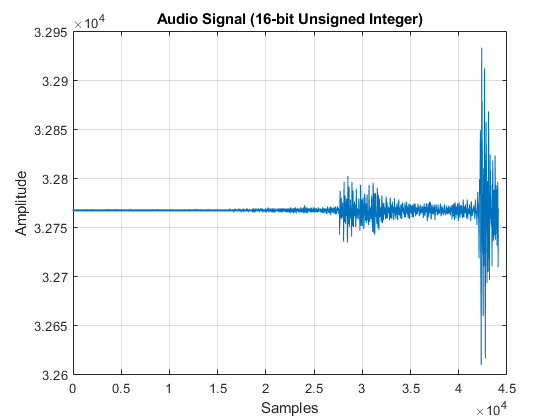


% Retrieve audio data
audioData = getaudiodata(recObj);

% Convert audio data to 16-bit unsigned integer with positive values
audioData = uint16((audioData + 1) * (2^15 - 1)); % Normalize and scale to 16-bit range

% Plot the waveform
figure;
plot(audioData);
title('Audio Signal (16-bit Unsigned Integer)');
xlabel('Samples');
ylabel('Amplitude');
grid on;


% Play the recorded audio (scaled back to original range for playback)
disp('Playing recorded audio...');

Playing recorded audio...


sound(double(audioData) / (2^15 - 1) - 1, fs);

% Write audio data to a coefficient file for Vivado
fid = fopen('audio_coefficients.coe', 'w');
fprintf(fid, 'memory_initialization_radix=16;');
fprintf(fid, 'memory_initialization_vector=');
for i = 1:length(audioData)
    fprintf(fid, '%04X', audioData(i));
    if i ~= length(audioData)
        fprintf(fid, ',');
    else
        fprintf(fid, ';');
    end
end
fclose(fid);
disp('Coefficient file audio_coefficients.coe generated successfully.');

Coefficient file audio_coefficients.coe generated successfully.
